x = PosMAT(:,1);
y = PosMAT(:,2);
vx = VelMAT(:,1);
vy = VelMAT(:,2);
ax = AccMAT(:,1);
ay = AccMAT(:,2);
jx = JerkMAT(:,1);
jy = JerkMAT(:,2);
sx = SnapMAT(:,1);
sy = SnapMAT(:,2);

AbsV = [];
Ex = [];
Ey = [];
Error = [];
len = length(PosMAT)

len = 3188

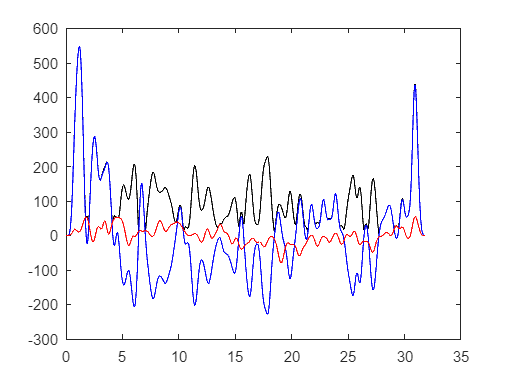

for i = 2:1:len
    Eulerx = (x(i)-x(i-1))/pstep;
    Ex = [Ex; Eulerx, i];
    Eulery = (y(i)-y(i-1))/pstep;
    Ey = [Ey; Eulery, i];
    abs = sqrt(Eulerx^2+Eulery^2);
    AbsV = [AbsV; abs, i];
    Error = [Error; (abs - VMagMAT(i, 2))/abs];
end
plot(AbsV(:,2)/100, AbsV(:,1), 'black')
hold on
plot(Ex(:,2)/100, Ex(:,1), 'blue')
plot(Ey(:,2)/100, Ey(:,1), 'red')
%plot(Ex(:,1), Ey(:,1))
%plot(VMagMAT(:,1)/100, -VMagMAT(:,2))
hold off

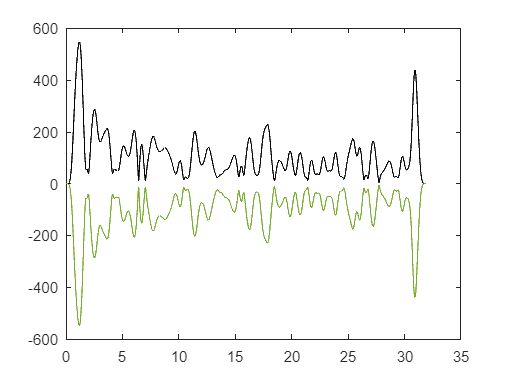

%plot(VelMAT(:,1),VelMAT(:,2))
plot(AbsV(:,2)/100, AbsV(:,1), 'black')
hold on
plot(VMagMAT(:,1)/100, -VMagMAT(:,2), 'Color', '#77AC30')
hold off

plot(Ex(:,2)*pstep, Error, 'black')
hold on
xlabel('Time')
ylabel('Relative Error')
%xlim([0, 35])
ylim([-8, 2])
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% REPEATED AS IM LAZY AT CODING

AbsV = [];
Ex = [];
Ey = [];
len = length(VelMAT)

len = 3188

Error = [];
for i = 2:1:len
    Eulerx = (vx(i)-vx(i-1))/pstep;
    Ex = [Ex; Eulerx, i];
    Eulery = (vy(i)-vy(i-1))/pstep;
    Ey = [Ey; Eulery, i];
    abs = sqrt(Eulerx^2+Eulery^2);
    AbsV = [AbsV; abs, i];
    Error = [Error; (abs - AMagMAT(i, 2))/abs];
end
plot(Ex(:,2)*pstep, Error, 'Color', "#A2142F")

AbsV = [];
Ex = [];
Ey = [];
len = length(AccMAT)

len = 3188

Error = [];
for i = 2:1:len
    Eulerx = (ax(i)-ax(i-1))/pstep;
    Ex = [Ex; Eulerx, i];
    Eulery = (ay(i)-ay(i-1))/pstep;
    Ey = [Ey; Eulery, i];
    abs = sqrt(Eulerx^2+Eulery^2);
    AbsV = [AbsV; abs, i];
    Error = [Error; (abs - JMagMAT(i, 2))/abs];
end
plot(Ex(:,2)*pstep, Error, 'blue')

AbsV = [];
Ex = [];
Ey = [];
len = length(JerkMAT)

len = 3188

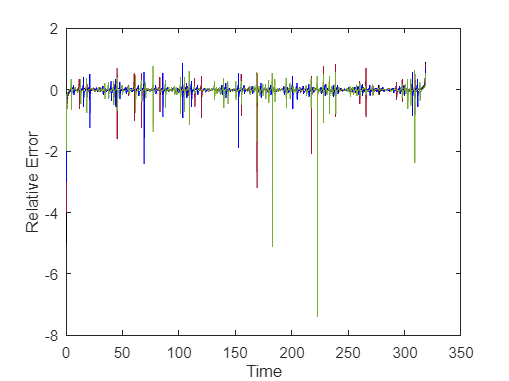

Error = [];
for i = 2:1:len
    Eulerx = (jx(i)-jx(i-1))/pstep;
    Ex = [Ex; Eulerx, i];
    Eulery = (jy(i)-jy(i-1))/pstep;
    Ey = [Ey; Eulery, i];
    abs = sqrt(Eulerx^2+Eulery^2);
    AbsV = [AbsV; abs, i];
    Error = [Error; (abs - SMagMAT(i, 2))/abs];
end
plot(Ex(:,2)*pstep, Error, 'Color', "#77AC30")